# Monte Carlo MOLI runs

Default config

%close all;
clear;
clc;
set(0,'defaultfigurecolor',[1 1 1]);

Initialize variables and set the Monte Carlo configurations

MCruns = 100;

par = cell(MCruns,1);
struc = cell(MCruns,1);
J = cell(MCruns,1);

## Generate the data or load pre-saved ones

Define the number of information data

WL = autoGen(14);
[dtd,dtn,A] = alertness_gen(2,WL,'random','not');
%load('monte_data.mat');

est_d = 7;

dte.y = dtd.y(1:est_d); dte.t = dtd.t(1:est_d);
dte.init = dtd.initial(1:est_d); dte.final = dtd.final(1:est_d); 
dte.valid.y = dtd.y(est_d+1:end); dte.valid.t = dtd.t(est_d+1:end);
dte.valid.init = dtd.initial(est_d+1:end); dte.valid.final = dtd.final(est_d+1:end);

A.valid.Ad = A.Ad(est_d+1:end); A.valid.td = A.td(est_d+1:end);
A.valid.An = A.An(est_d+1:end); A.valid.tn = A.tn(est_d+1:end);

Create  a variable for noise manipulation on simulation

y_c = dte.y;

## Initialize the Monte Carlo Simulations

n_s = 1;
for mc = 1 : MCruns
    
    rng('shuffle');
    
    noise_nat = 'colored';
    SNR = 40;
    to = cell2mat(dte.t);

    if strcmp(noise_nat,'white')
        %e = cell2mat(y_c) - awgn(cell2mat(y_c),SNR);
        e = idinput(length(cell2mat(y_c)),'rgs')*...
                                          std(cell2mat(y_c))*10^(-SNR/20);
        yo = cell2mat(y_c) + e;
    elseif strcmp(noise_nat,'colored')
        e = filter(1,[1 -.9],randn(length(cell2mat(y_c)),1));
        v = e*std(cell2mat(y_c))*10^(-SNR/20)/std(e);
        e = v;
        yo = cell2mat(y_c) + e;
    elseif strcmp(noise_nat,'noNoise')
        yo = cell2mat(y_c);
    end

    for w = 1 : length(y_c)
       ind = find((to>=dte.t{w}(1)).*(to<=dte.t{w}(end)));
       dte.y{w} = yo(ind);
    end
    
    struc{mc} = struc_select('trivial',dte);
    
    par{mc} = est_regr(dte,struc{mc},'16');

    time.init = [dte.valid.t{1}(1), dte.valid.init(2:end)];
    time.final = dte.valid.final;
    initial = dte.valid.y{1}(1);
    
    dts = sim_system(par{mc},time,initial);
    
    fit = e_quad(dts,dte.valid);
     
    J{mc} = fit.quadratic;
    
    disp(['Monte Carlo run ',num2str(mc),...
                             ' Quadratic Error: ',num2str(fit.quadratic)]);
    
end

Monte Carlo run 1 Quadratic Error: 0.8706
Monte Carlo run 2 Quadratic Error: 0.0014305
Monte Carlo run 3 Quadratic Error: 6.8584
Monte Carlo run 4 Quadratic Error: 0.70306
Monte Carlo run 5 Quadratic Error: 0.4671
Monte Carlo run 6 Quadratic Error: 3.6469
Monte Carlo run 7 Quadratic Error: 1.9596
Monte Carlo run 8 Quadratic Error: 0.11952
Monte Carlo run 9 Quadratic Error: 0.65966
Monte Carlo run 10 Quadratic Error: 4.374
Monte Carlo run 11 Quadratic Error: 0.551
Monte Carlo run 12 Quadratic Error: 0.32372
Monte Carlo run 13 Quadratic Error: 0.69077
Monte Carlo run 14 Quadratic Error: 2.2148
Monte Carlo run 15 Quadratic Error: 0.65752
Monte Carlo run 16 Quadratic Error: 0.025305
Monte Carlo run 17 Quadratic Error: 4.4
Monte Carlo run 18 Quadratic Error: 0.0018206
Monte Carlo run 19 Quadratic Error: 5.8355
Monte Carlo run 20 Quadratic Error: 1.5136
Monte Carlo run 21 Quadratic Error: 0.10445
Monte Carlo run 22 Quadratic Error: 1.8789
Monte Carlo run 23 Quadratic Error: 0.24474
Monte Car

## Signal to Noise Ratio Histogram

Create the histogram to prove the Signal to Noise Ratio checkout

%figure(8); hold on; histogram(SNR_check,20);

## Parameters error analisys

Determine the error for each parameter estimated at each noise realization

E = zeros(MCruns,9);

for mc = 1 : MCruns
   
   E(mc,1) = (par{mc}.est.omega - par{mc}.real.omega)/par{mc}.real.omega; 
   E(mc,2) = (par{mc}.est.tau - par{mc}.real.tau)/par{mc}.real.tau; 
   E(mc,3) = (par{mc}.est.cphase - ...
                                  par{mc}.real.cphase)/par{mc}.real.cphase;
   E(mc,4) = (par{mc}.est.M - par{mc}.real.M)/par{mc}.real.M;
   E(mc,6) = (par{mc}.est.offset - par{mc}.real.offset)/par{mc}.real.offset;
   E(mc,7) = (par{mc}.est.y_oo - par{mc}.real.y_oo)/par{mc}.real.y_oo;
   E(mc,8) = (par{mc}.est.tau_e - par{mc}.real.tau_e)/par{mc}.real.tau_e;
   
   for k = 1 : length(par{mc}.est.h0) 
       E(mc,5) = E(mc,5) + (par{mc}.est.h0(k) - par{mc}.real.h0(k))^2;
   end
   
   E(mc,5) = E(mc,5)^.5/length(par{mc}.est.h0);
   
   for k = 1 : length(par{mc}.est.h0) 
       E(mc,9) = E(mc,9) + (par{mc}.est.h0(k) + par{mc}.est.offset ...
                    - par{mc}.real.h0(k) - par{mc}.real.offset)^2;
   end
   
   E(mc,9) = E(mc,9)^.5/length(par{mc}.est.h0);    
end

E = 100.*E;

## Error test

Test the possibility of another parameter recuperation.

E_ = zeros(MCruns,2);
for mc = 1 : MCruns
   E_(mc,1) = (par{mc}.est.omega_ - par{mc}.real.omega)/par{mc}.real.omega; 
   E_(mc,2) = (par{mc}.est.tau_ - par{mc}.real.tau)/par{mc}.real.tau;  
end

E_ = 100.*E_;

## Structure errors

Determine the structure errors, such as the parameters from $B$ and $A$ matrices.

E_a = zeros(MCruns,4);
E_b = zeros(MCruns,4);
for mc = 1 : MCruns
    
    error = zeros(4,1);
    for j = 1 : length(dte.y)
        error = error + abs(par{mc}.real.struc.B{j}...
                            - par{mc}.est.struc.B{j})./...
                                 abs(par{mc}.real.struc.B{j});
    end
    error = error ./ length(dte.y);
    
    for i = 1 : 4
        E_b(mc,i) = error(i);
        if i == 1
            E_a(mc,i) = par{mc}.real.struc.A(i,4)...
                            - par{mc}.est.struc.A(i,4);
        else
            E_a(mc,i) = (par{mc}.real.struc.A(i,4)...
                            - par{mc}.est.struc.A(i,4))./...
                                    abs(par{mc}.real.struc.A(i,4));
        end
    end
end

## Plotting parameters error results

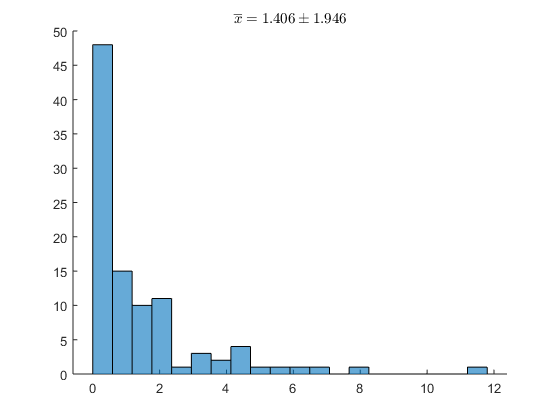

figure(9); hold on;
histogram(cell2mat(J),20);
title(['$$\overline{x} =',num2str(round(mean(cell2mat(J)),3)),...
     '\pm',num2str(round(std(cell2mat(J)),3)),'$$'],'Interpreter','latex');

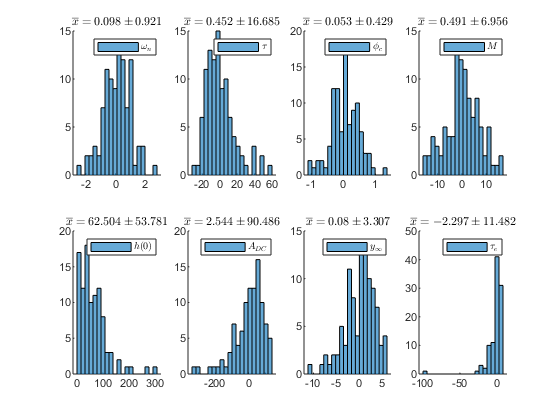


figure(10); hold on;
for k = 1 : 8
    subplot(2,4,k); hold on;
    histogram(E(:,k),20); hold on;
    title(['$$\overline{x} =',num2str(round(mean(E(:,k)),3)),...
          '\pm',num2str(round(std(E(:,k)),3)),'$$'],'Interpreter','latex');
    leg = par{1}.TexNames{k};
    %xlim([-100,100]);
    legend([{leg}],'Interpreter','latex'); hold off;
end

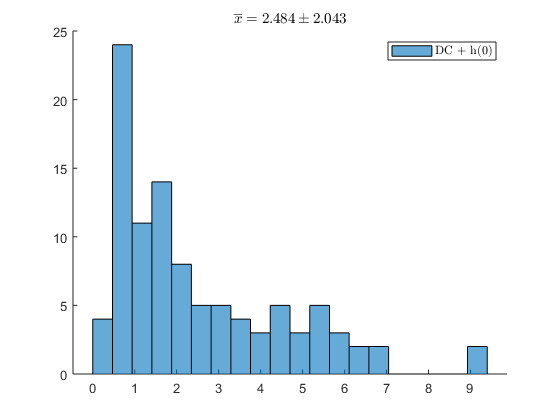


figure(11); hold on;
histogram(E(:,9),20); hold on;
title(['$$\overline{x} =',num2str(round(mean(E(:,9)),3)),...
         '\pm',num2str(round(std(E(:,9)),3)),'$$'],'Interpreter','latex');
leg = 'DC + h(0)';
%xlim([-100,100]);
legend([{leg}],'Interpreter','latex'); hold off;

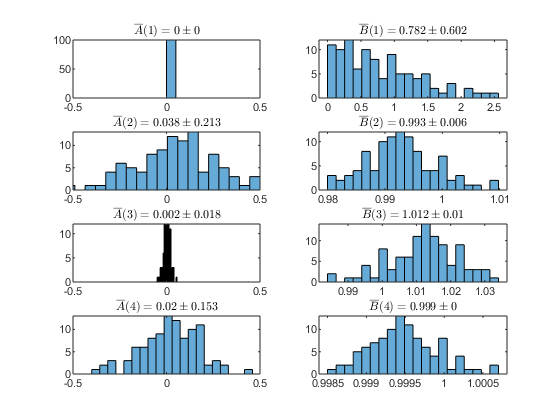


figure(12); hold on;
k = 1; z = 1;
for i = 1:2:8
    subplot(4,2,i); 
    histogram(E_a(:,k),20); hold on;
    title(['$$\overline{A}(',num2str(k),') =',...
            num2str(round(mean(E_a(:,k)),3)),'\pm',...
             num2str(round(std(E_a(:,k)),3)),'$$'],'Interpreter','latex');
    xlim([-.5,.5]); hold off; k = k + 1;
    
    subplot(4,2,i+1);
    histogram(E_b(:,z),20); hold on;
    title(['$$\overline{B}(',num2str(z),') =',...
            num2str(round(mean(E_b(:,z)),3)),'\pm',...
             num2str(round(std(E_b(:,z)),3)),'$$'],'Interpreter','latex');
    hold off; z = z + 1;
end

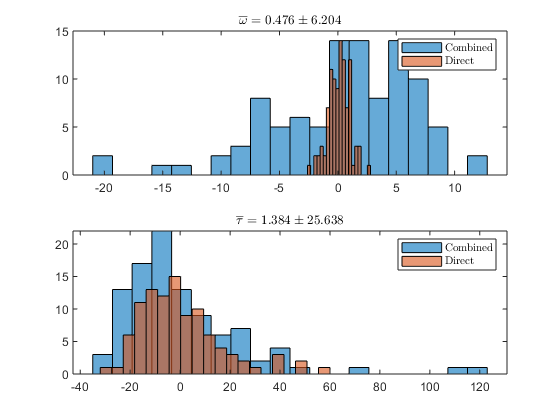


figure(13); hold on;
subplot(2,1,1);
histogram(E_(:,1),20); hold on;
histogram(E(:,1),20); hold on;
title(['$$\overline{\omega} =',num2str(round(mean(E_(:,1)),3)),...
      '\pm',num2str(round(std(E_(:,1)),3)),'$$'],'Interpreter','latex');
legend([{'Combined'},{'Direct'}],'Interpreter','latex'); hold off;

subplot(2,1,2);
histogram(E_(:,2),20); hold on;
histogram(E(:,2),20); hold on;
title(['$$\overline{\tau} =',num2str(round(mean(E_(:,2)),3)),...
       '\pm',num2str(round(std(E_(:,2)),3)),'$$'],'Interpreter','latex');
legend([{'Combined'},{'Direct'}],'Interpreter','latex'); hold off;